clc 
close all

## Original Signal plot

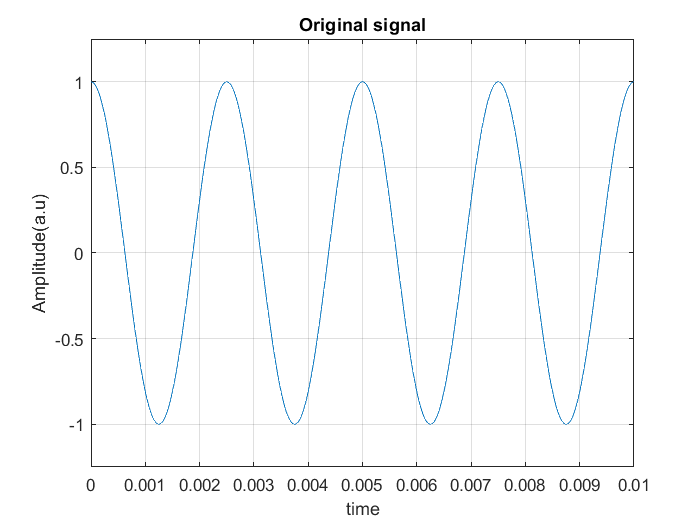

%Specifications given
f = 400;
A = 1;
t = 0:0.00001:0.01;

%Defining the orginal signal
y_t = A*cos(2*pi*f*t);

%plotting the original signal
plot(t,y_t)
title("Original signal")
xlabel("time")
ylabel("Amplitude(a.u)")
axis([0 0.01 -1.25 1.25])
grid on

## Calculating the Nyquist sampling frequency


f_s = 2*f;

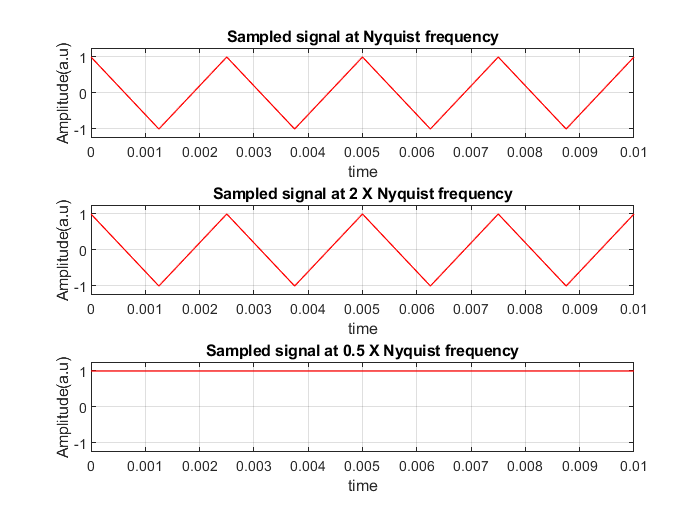

%time vector for the sampled signal
ts1 = 0:(1/f_s):0.01;

y_ts1 = A*cos(2*pi*f*ts1);

subplot(3,1,1)
plot(ts1,y_ts1,'r','LineWidth',0.75)
title("Sampled signal at Nyquist frequency")
xlabel("time")
ylabel("Amplitude(a.u)")
axis([0 0.01 -1.25 1.25])
grid on

%time vector for the sampled signal (2nq)
ts2 = 0:(1/(2*f_s)):0.01;

y_ts2 = A*cos(2*pi*f*ts2);

subplot(3,1,2)
plot(ts2,y_ts2,'r','LineWidth',0.75)
title("Sampled signal at 2 X Nyquist frequency")
xlabel("time")
ylabel("Amplitude(a.u)")
axis([0 0.01 -1.25 1.25])
grid on

%time vector for the sampled signal (0.5nq)
ts_half = 0:(1/(0.5*f_s)):0.01;

y_ts_half = A*cos(2*pi*f*ts_half);

subplot(3,1,3)
plot(ts_half,y_ts_half,'r','LineWidth',0.75)
title("Sampled signal at 0.5 X Nyquist frequency")
xlabel("time")
ylabel("Amplitude(a.u)")
axis([0 0.01 -1.25 1.25])
grid on

## Quantizing the signal sampled at 8 X Nyquist frequency (L levels)

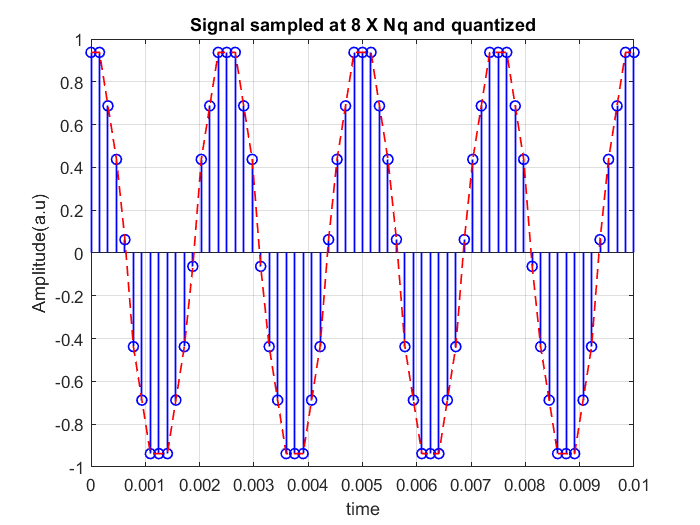

%sampling the signal at 8nq
ts8 = 0:(1/(8*f_s)):0.01;

y_ts8 = A*cos(2*pi*f*ts8);

%Defining the quantization levels and bits
bits = 4;
qlevels = 2^bits;

%scaling the signal
scalingFactor = (A-(-A))/qlevels;
y_ts8_q = y_ts8/scalingFactor;

%rounding to the midpoints
roundTargets = [-7.5:1.0:7.5];
y_ts8_q = interp1(roundTargets,roundTargets,y_ts8_q,'nearest','extrap');

%rescaling to the original amplitude
y_ts8_q = (y_ts8_q)*scalingFactor;

%plotting the quantized signal
figure;
stem(ts8,y_ts8_q,'b','LineWidth',1)
hold on
plot(ts8,y_ts8_q,'r--','LineWidth',1)
xlabel ('time')
ylabel('Amplitude(a.u)')
title('Signal sampled at 8 X Nq and quantized')
grid on

## Quantizing the signal sampled at 8 X Nyquist frequency (L/2 levels) 

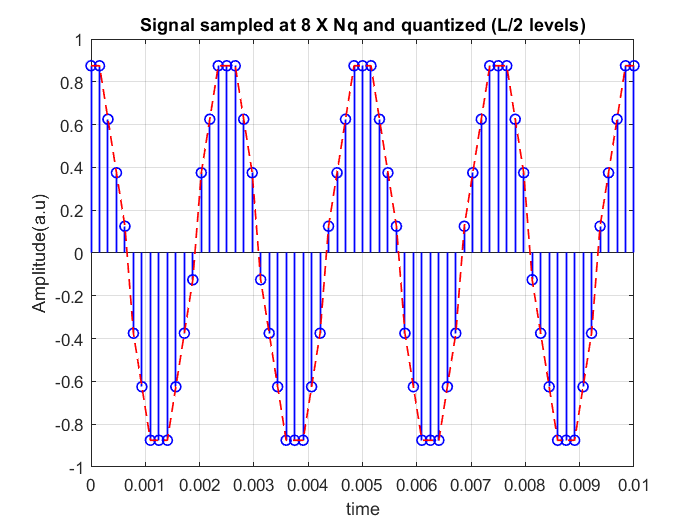

%Defining the quantization levels and bits
bits = 3;
qlevels = 2^bits;

%scaling the signal
scalingFactor = (A-(-A))/qlevels;
y_ts8_q = y_ts8/scalingFactor;

%rounding to the midpoints
roundTargets = [-3.5:1.0:3.5];
y_ts8_q = interp1(roundTargets,roundTargets,y_ts8_q,'nearest','extrap');

%rescaling to the original amplitude
y_ts8_q = (y_ts8_q)*scalingFactor;

%plotting the quantized signal
figure;
stem(ts8,y_ts8_q,'b','LineWidth',1)
hold on
plot(ts8,y_ts8_q,'r--','LineWidth',1)
xlabel ('time')
ylabel('Amplitude(a.u)')
title('Signal sampled at 8 X Nq and quantized (L/2 levels)')
grid on

## Quantizing the signal sampled at 8 X Nyquist frequency (L*2 levels) 

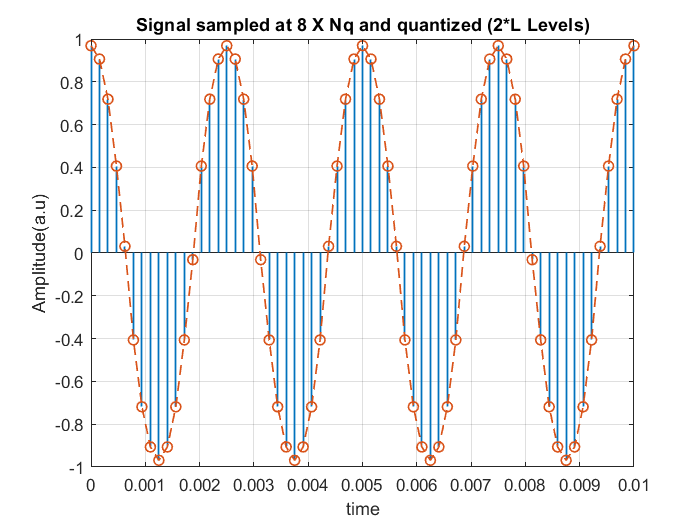

%Defining the quantization levels and bits
bits = 5;
qlevels = 2^bits;

%scaling the signal
scalingFactor = (A-(-A))/qlevels;
y_ts8_q = y_ts8/scalingFactor;

%rounding to the midpoints
roundTargets = [-15.5:1.0:15.5];
y_ts8_q = interp1(roundTargets,roundTargets,y_ts8_q,'nearest','extrap');

%rescaling to the original amplitude
y_ts8_q = (y_ts8_q)*scalingFactor;

%plotting the quantized signal
figure;
stem(ts8,y_ts8_q,'o','LineWidth',1)
hold on
plot(ts8,y_ts8_q,'o--','LineWidth',1)
xlabel ('time')
ylabel('Amplitude(a.u)')
title('Signal sampled at 8 X Nq and quantized (2*L Levels)')
grid on